# Nine bus power system network

The following demonstration deals with a nine bus inverter-based power network model, based on the example presented in [[1]](https://ieeexplore.ieee.org/document/8428437).

[Open Live Script in Matlab](matlab:open('nine_bus_demo_dmss.mlx'))

### Inverter Model

The schematic for a grid-forming droop-controlled voltage source inverter used in this demostration is shown below.

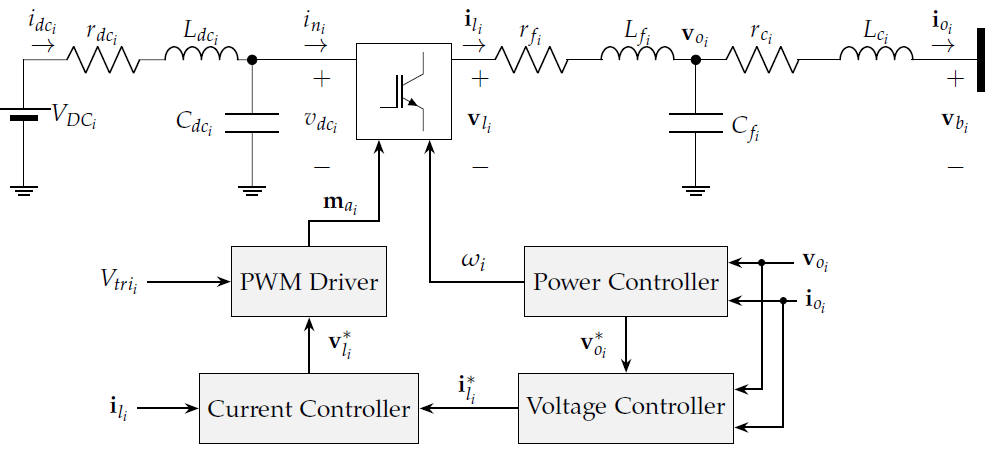

**Figure 1. Inverter scheme**

The parameters of the inverter model are given in [[1]](https://ieeexplore.ieee.org/document/8428437), however these can also be found in the following script.

nine_bus_parameters;

Inverter parameters in workspace


In order for a dmss object to be created the governing equations must be written down as symbolic realtions. As an example, considering the DC input side of an inverter $i$, in the network yields,

$
\frac{\text{d}}{\text{d}t}v_{\text{dc}_i} = \frac{1}{C_{\text{dc}_i}}i_{\text{dc}_i} - \frac{P_i}{C_{\text{dc}_i}v_{\text{dc}_i}}
$,

where the reciprocal realtion on the voltage $v_{\text{dc}_i}$ is a nonlinear term. This nonlinearity can be adapted and handled as a dmss object by substituting additional algebraic variables and constraints. 


$$\frac{\text{d}}{\text{d}t}v_{\text{dc}_i} = \frac{1}{C_{\text{dc}_i}}i_{\text{dc}_i} - \frac{P_i z_{\text{dc}_i}}{C_{\text{dc}_i}}, \\
        0 = z_{\text{dc}_i} v_{\text{dc}_i} - 1.$$


The equations of the DC input are declared, for the nine inverters, as

% Variables
num_inv = 9;
idc = symSingleVars('idc',num_inv); 
vdc = symSingleVars('vdc',num_inv)

$$vdc = \left(\begin{array}{c} {\mathrm{vdc}}_{1}\left(t\right)\\ {\mathrm{vdc}}_{2}\left(t\right)\\ {\mathrm{vdc}}_{3}\left(t\right)\\ {\mathrm{vdc}}_{4}\left(t\right)\\ {\mathrm{vdc}}_{5}\left(t\right)\\ {\mathrm{vdc}}_{6}\left(t\right)\\ {\mathrm{vdc}}_{7}\left(t\right)\\ {\mathrm{vdc}}_{8}\left(t\right)\\ {\mathrm{vdc}}_{9}\left(t\right) \end{array}\right)$$

zdc = symSingleVars('zdc',num_inv);
P = symSingleVars('P',num_inv);

% Equations
syms t
eq1 = diff(idc,t)== Ldc\(-rdc*idc - vdc + Vdc);
eq2 = diff(vdc,t) == Cdc\(idc-P.*zdc);
eq3 = zdc.*vdc-1==0;

where equations for the first inverter can be visualized as,

vpa([eq1(1);eq2(1);eq3(1)],3)

$$ans = \left(\begin{array}{c} \frac{\partial }{\partial t}{\mathrm{idc}}_{1}\left(t\right)=1000.0-1.0\,{\mathrm{vdc}}_{1}\left(t\right)-28.9\,{\mathrm{idc}}_{1}\left(t\right)\\ \frac{\partial }{\partial t}{\mathrm{vdc}}_{1}\left(t\right)=0.2\,{\mathrm{idc}}_{1}\left(t\right)-0.2\,P_{1}\left(t\right)\,{\mathrm{zdc}}_{1}\left(t\right)\\ {\mathrm{vdc}}_{1}\left(t\right)\,{\mathrm{zdc}}_{1}\left(t\right)-1.0=0.0 \end{array}\right)$$

here the coefficients have been rounded for better visibility.

The modeling of the network is done using the direct-quadrature-zero or $\textrm{dq0}$ rotating frame, where all three-phase vector variables are mapped into two-component vectors. Within the network one inverter is chosen as the global reference frame $\textrm{DQ}$ which is also taken as the frame of the network. All other inveter are assinged a local ${\textrm{dq}}_i$ frame. The transformation from a local frame to the global frame is achieved as a simple matrix rotation,

$\mathbf{T}_i =\bigg\lbrack \matrix{\cos(\delta_i) & -\sin(\delta_i) \cr \sin(\delta_i)  & \cos(\delta_i)} \bigg\rbrack $,

where $\delta_i
$ is the angle between the local ${\textrm{dq}}_i$ and global $\textrm{DQ}$ frames. When dealing with cosine and sine functions, a variable substitution as, $\mathbf{x}_{{\text{trig}}_i} := [x_{{\text{trig}}_{2i-1}}\quad x_{{\text{trig}}_{2i}}]^\text{T} = [\mathrm{cos}(\delta_i)\quad \mathrm{sin}(\delta_i)]^\text{T}$, can be used for any inverter $i$. The additional equations, 

$\frac{\text{d}}{\text{d}t}\mathbf{x}_{{\text{trig}}_i} =
 \Bigg\lbrack\matrix{
        \dot{x}_{{\text{trig}}_{2i-1}} \cr
        \dot{x}_{{\text{trig}}_{2i}}
 } \Bigg\rbrack = \dot{\delta}_i  \Bigg\lbrack\matrix{
        -x_{{\text{trig}}_{2i}} \cr x_{{\text{trig}}_{2i-1}}
} \Bigg\rbrack$,

must be added to account for the time evolution of these new variables. The remaing inverter equations, which include the LCL-output circuit and controllers, are declared with the following script.

nine_bus_inverters;

Inverter equations in workspace


For example, the second inverter's transformation matrix and additional equations are,

disp('T2 = ')

T2 = 


TDQ(3:4,3:4)

$$ans = \left(\begin{array}{cc} {\mathrm{xtrig}}_{3}\left(t\right) & {\mathrm{xtrig}}_{4}\left(t\right)\\ -{\mathrm{xtrig}}_{4}\left(t\right) & {\mathrm{xtrig}}_{3}\left(t\right) \end{array}\right)$$

[eq_dz_odd(2);eq_dz_even(2)]

$$ans = \left(\begin{array}{c} \frac{\partial }{\partial t}{\mathrm{xtrig}}_{3}\left(t\right)=-{\mathrm{xtrig}}_{4}\left(t\right)\,\frac{\partial }{\partial t}\delta_{2}\left(t\right)\\ \frac{\partial }{\partial t}{\mathrm{xtrig}}_{4}\left(t\right)={\mathrm{xtrig}}_{3}\left(t\right)\,\frac{\partial }{\partial t}\delta_{2}\left(t\right) \end{array}\right)$$

where the equations can be handled by a dmss object.

### Network Model

The three bus network from  [[1]](https://ieeexplore.ieee.org/document/8428437), serves as the building block for this demonstration, it consists of a network with a nominal frequency of 50 Hz and a nominal voltage of 310 V. The generation is done by voltage source DC-AC inverters and the loads are purely resistive.

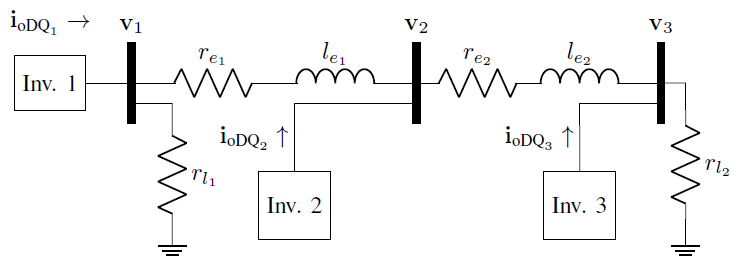

**Figure 2. Three bus network scheme**

The nine bus network is created out of interconnected three-bus units in a ring arrangement for this demonstration. The scheme is depicted here in **Figure 3**, where each block has the same structure as in **Figure 2**. 

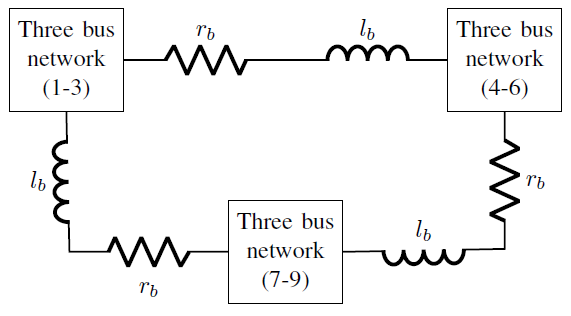

**Figure 3. Nine bus network scheme**

The network load configuration can be gradually switch between two conductance matrices $\mathbf{G}_1 $and $\mathbf{G}_2$ with the use of an external saturation function $u_1 \in [0, 1]$ as,

$\mathbf{G} = u_1\mathbf{G}_1  + (1-u_1)\mathbf{G}_2 $,

 where $\mathbf{G}$is the overall conductance matrix of the network. The topology, parameters, incidence matrix, and governing equations of the network are declared in the next script.

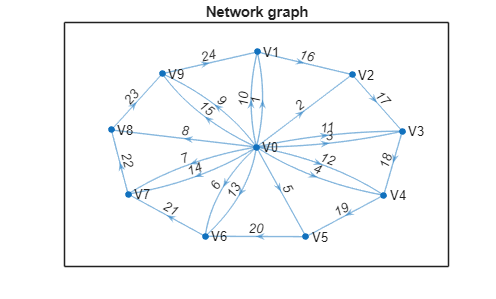

Bus V0 is ground.
Network equations in workspace


nine_bus_network;

In order to link both sets of inveters and network equations, the injected generation currents into the nodes are matched with the output currents of the inverters, also the voltages at each node is matched with the inverter output voltage. This is done for a nonlinear as well as a multilinear model, in the next script.

### Nine bus model

nine_bus_equations;

origVars = length(vars);
origeqns = length(eqns);
disp(['Number of variables in multilinear model: ',num2str(origVars)]); 

Number of variables in multilinear model: 198


disp(['Number of equations in multilinear model: ',num2str(origeqns)]); 

Number of equations in multilinear model: 198


disp("Multilinear equations now in workspace")

Multilinear equations now in workspace



origVars_nl = length(vars_nl);
origeqns_nl = length(eqns_nl);
disp(['Number of variables in nonlinear model: ',num2str(origVars_nl)]); 

Number of variables in nonlinear model: 171


disp(['Number of equations in nonlinear model: ',num2str(origeqns_nl)]); 

Number of equations in nonlinear model: 171


disp("Nonlinear equations now in workspace")

Nonlinear equations now in workspace


A necesarry step before attempting to simulate the network is to make sure that the governing equations are of differential index one, [[2]](https://link.springer.com/referenceworkentry/10.1007/978-3-540-70529-1_120). The following steps one way to do this.

% Reduce differential order to one.
 disp("Reducing differential order")

Reducing differential order


 [eqns_nl,vars_nl] = reduceDifferentialOrder(eqns_nl,vars_nl);
 [eqns,vars] = reduceDifferentialOrder(eqns,vars)  ;
 
% Index test.
 is_low_indx_nl = isLowIndexDAE(eqns_nl,vars_nl);
 is_low_indx = isLowIndexDAE(eqns,vars);
 
 disp("Are DAEs low Index?: ")

Are DAEs low Index?: 


 disp(['Nonlinear?: '   ,num2str(is_low_indx_nl)])

Nonlinear?: 1


 disp(['Multilinear?: ',num2str(is_low_indx)])

Multilinear?: 1




 % If differential index is high, attempt to reduce.
 if ~is_low_indx_nl
     disp("Reducing the index nonlinear")
     [DAEs_nl,DAEvars_nl] = reduceDAEIndex(eqns_nl,vars_nl);
    
     disp("Reducing redundancies nonlinear")
     [DAEs_nl,DAEvars_nl] = reduceRedundancies(DAEs_nl,DAEvars_nl);
     redVars_nl = length(DAEvars_nl);
    
     disp("Is nonlinear DAE now low Index?: ")
     disp(isLowIndexDAE(DAEs_nl,DAEvars_nl))
 end

 % Check if index reduction was successful
 if ~is_low_indx
     disp("Reducing the index")
     [DAEs,DAEvars] = reduceDAEIndex(eqns,vars);
    
     disp("Reducing redundancies")
     [DAEs,DAEvars] = reduceRedundancies(DAEs,DAEvars);
     redVars = length(DAEvars);
    
     disp("Is DAE now low Index?: ")
     disp(isLowIndexDAE(DAEs,DAEvars))
 end

### Create a dmss object for the model

To create a dmss object, the member function sym2dmss is utilized. This function takes a set of symbolic equations and returns the dmss object. The function uses the symbolic variables [xp, x, u, y], as state derivatives, states, inputs, algebraic variables respectively. In order to pass the network equations, all variables are replaced by [xp, x, u, y].

% Determine number of differentiable states, inputs and algebraic variables.

% There are 15 states in each inverter, 2 states in each line, and 2
% extra states for the additional xtrig variables.
n_diff = num_inv*15 + Lines*2 + num_inv*2;

% There is one input to trigger the load distrubance
m_inp = 1;

% The algebraic variables are left after taking all differentiable
% variables.
n_alg = origVars - n_diff; 

% Replace the state derivatives with xp
syms xp [n_diff 1]
eqns = subs(eqns,diff(vars(1:n_diff),t),xp);

% Replace the states with x
syms x [n_diff 1]
eqns = subs(eqns,vars(1:n_diff),x);

% Replace the algebraic variables with y
syms y [n_alg 1]
eqns = subs(eqns,vars(n_diff+1:end),y);

% Replace the input variables with u
%syms u [m_inp 1]
%eqns = subs(eqns,u_1,u);


The dmss object is created by passing the set of equations and a possible discretization time $\text{t}_s
$. The returned object is a continous dmss when $\text{t}_s = 0

$, otherwise it is discrete dmss with the chosen sample time.

ts = 0;
MMtic=tic;
sys = sym2dmss(0==eqns,ts) % add "0 = " to the LEFT to form the equations 

Reduced by 411 column(s) and 0 equation(s) with trivial Reduction due to duplications.


sys =   dmss with properties:

                          H: [1×1 hyCPN1]
                          n: 171
                          m: 1
                          p: 27
                          q: 0
                outputIndex: [1×1 struct]
                        nEq: 198
                      nIneq: 0
                  stateName: [0×0 string]
                  stateUnit: [0×0 string]
              algebraicName: [0×0 string]
              algebraicUnit: [0×0 string]
                  inputName: [0×0 string]
                  inputUnit: [0×0 string]
                booleanName: [0×0 string]
                booleanUnit: [0×0 string]
        manipulatedVariable: []
        measuredDisturbance: []
      unmeasuredDisturbance: []
                         ts: 0
    discreteDifferentiation: "none"


MMtoc=toc(MMtic);
fprintf('%.2f sec - Multilinear model\n', MMtoc) 

14.08 sec - Multilinear model


### Simulate the model, multilinear and nonlinear

In order to compare the models, the first simulation is done on the nonlinear set of equations followed by simulation of the multilinear system using the dmsim function.

An estimate for initial conditions to both models is declared in the script below.

nine_bus_initial_conditions;

Initial conditions in workspace under y0est vector


#### Nonlinear simulation

Since the model is of differential index one, the ode15s solver can be utilized. For this, the nonlinear set of equations is arranged into the semilinear format $\mathbf{M}(t,\mathbf{x})\mathbf{\dot x}= \mathbf{f}(t,\mathbf{x})$.

MMtic=tic;
[M_nl,rhs_eqns_nl] = massMatrixForm(eqns_nl,vars_nl);
% Convert M to a function handle using odeFunction
M_nl = odeFunction(M_nl,vars_nl);
% Convert rhs_eqns to al function handle also
fh_nl = odeFunction(rhs_eqns_nl,vars_nl,u1);
MMtoc=toc(MMtic);
fprintf('%.2f sec - Semilinear model\n', MMtoc) 

19.32 sec - Semilinear model


The input saturation function for the transition between the two load configurations in the network, [[3]](https://www.researchgate.net/publication/357792332_Implicit_multilinear_modeling_An_introduction_with_application_to_energy_systems), is declared below. 

%% Create the ramp function and 
tl = 0.3; ul = 1;
tu = 0.301; uu = 0; % tu-tl would be the "transition" time of the ramp
s = (uu-ul)/(tu-tl);
bl = @(t) heaviside(t-tl);
bu = @(t) heaviside(t-tu);u1 =  @(t) (1-bl(t))*ul + bl(t).*(1-bu(t)).*((t-tl).*s + ul) + bu(t)*uu;

Consistent initial conditions for the nonlinear model can be obtained by using the decic function.

%% Create function handle for nonlinear model
Fh_nl = @(t,Y) fh_nl(t,Y,u1(t)); 

opt_nl = odeset('Mass',M_nl,'InitialSlope',zeros(size(vars_nl))); 
implicitDAE_nl = @(t,y,yp) M_nl(t,y)*yp-Fh_nl(t,y);

% Enforcing initial conditions leads to stable solutions, it also forces the both simulations 
% to start at apporximatly the same point.
y0hold = zeros(size(vars_nl)); 

disp("The following initial conditions for states are enforced.")

The following initial conditions for states are enforced.


disp("Angle deviations") 

Angle deviations


vars_nl(2*num_inv+1:3*num_inv)

$$ans = \left(\begin{array}{c} \delta_{1}\left(t\right)\\ \delta_{2}\left(t\right)\\ \delta_{3}\left(t\right)\\ \delta_{4}\left(t\right)\\ \delta_{5}\left(t\right)\\ \delta_{6}\left(t\right)\\ \delta_{7}\left(t\right)\\ \delta_{8}\left(t\right)\\ \delta_{9}\left(t\right) \end{array}\right)$$

y0hold(2*num_inv+1:3*num_inv) = ones(size(delta0)); % force angle displacement

disp("Inverter output currents") 

Inverter output currents


vars_nl(13*num_inv+1:15*num_inv)

$$ans = \left(\begin{array}{c} \mathrm{io1d}\left(t\right)\\ \mathrm{io1q}\left(t\right)\\ \mathrm{io2d}\left(t\right)\\ \mathrm{io2q}\left(t\right)\\ \mathrm{io3d}\left(t\right)\\ \mathrm{io3q}\left(t\right)\\ \mathrm{io4d}\left(t\right)\\ \mathrm{io4q}\left(t\right)\\ \mathrm{io5d}\left(t\right)\\ \mathrm{io5q}\left(t\right)\\ \mathrm{io6d}\left(t\right)\\ \mathrm{io6q}\left(t\right)\\ \mathrm{io7d}\left(t\right)\\ \mathrm{io7q}\left(t\right)\\ \mathrm{io8d}\left(t\right)\\ \mathrm{io8q}\left(t\right)\\ \mathrm{io9d}\left(t\right)\\ \mathrm{io9q}\left(t\right) \end{array}\right)$$

y0hold(13*num_inv+1:15*num_inv) = ones(1,2*9); % force inverter output currents

disp("Line currents") 

Line currents


vars_nl(15*num_inv+1:15*num_inv+2*Lines)

$$ans = \left(\begin{array}{c} \mathrm{f1d}\left(t\right)\\ \mathrm{f1q}\left(t\right)\\ \mathrm{f2d}\left(t\right)\\ \mathrm{f2q}\left(t\right)\\ \mathrm{f3d}\left(t\right)\\ \mathrm{f3q}\left(t\right)\\ \mathrm{f4d}\left(t\right)\\ \mathrm{f4q}\left(t\right)\\ \mathrm{f5d}\left(t\right)\\ \mathrm{f5q}\left(t\right)\\ \mathrm{f6d}\left(t\right)\\ \mathrm{f6q}\left(t\right)\\ \mathrm{f7d}\left(t\right)\\ \mathrm{f7q}\left(t\right)\\ \mathrm{f8d}\left(t\right)\\ \mathrm{f8q}\left(t\right)\\ \mathrm{f9d}\left(t\right)\\ \mathrm{f9q}\left(t\right) \end{array}\right)$$

y0hold(15*num_inv+1:15*num_inv+2*Lines) = ones(1,2*9); % force line currents


[y0_nl, yp0_nl] = decic(implicitDAE_nl,0,y0est(1:n_diff),y0hold,zeros(size(vars_nl)),[],opt_nl);
disp('Function decic found intial conditions for nonlinear model')

Function decic found intial conditions for nonlinear model


Now it is possible to simulate the nonlinear model.

tsim = 1; % simulation time
opt_nl = odeset(opt_nl,'InitialSlope',yp0_nl,'RelTol',1e-4,'AbsTol',1e-4);
[tSol_nl,ySol_nl] = ode15s(Fh_nl,[0, tsim],y0_nl,opt_nl);
disp('ode15s is done simulating the nonlinear model')

ode15s is done simulating the nonlinear model


#### Multilinear simulation with dmsim

The function dmsim is used to simulate the multilinear model as a dmss object. The function takes an dmss object, the initial condition set, and the input time and values. 

%% Input time
ut = 0:0.01:tsim;  

% Simulation with dmsim
sys_simulation = dmsim(sys,y0est(1:n_diff),[],[],ut,u1(ut)');


#### Plot comparison

The state trajectories can be accessed by the simulation structure sim, where plots can be drawn.

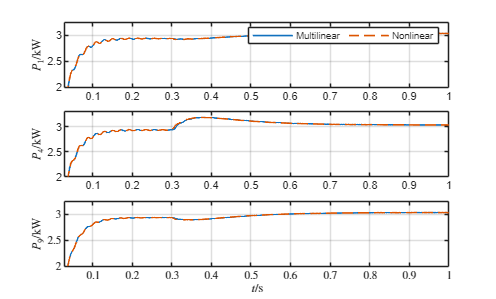

close all
% Power plots from sim object
figure(1)
P_indices = 3*num_inv+1:4*num_inv; % indices of the inverter active power

% Compare power in inverter 1
subplot(3,1,1)
plot(sys_simulation.tsim,sys_simulation.x(:,P_indices(1))./1000,LineWidth=1.2)
grid
hold on
plot(tSol_nl,ySol_nl(:,P_indices(1))./1000,'LineStyle', '--',LineWidth=1.2)
legend("Multilinear","Nonlinear",'Orientation','horizontal')
ylabel('$P_1/\textrm{kW}$','Interpreter','latex')
ylim([2 3.25])
xlim([0.03 1])

% Compare power in inverter 4
subplot(3,1,2)
plot(sys_simulation.tsim,sys_simulation.x(:,P_indices(4))./1000,LineWidth=1.2)
hold on
plot(tSol_nl,ySol_nl(:,P_indices(4))./1000,'LineStyle', '--',LineWidth=1.2)
grid
ylabel('$P_4/\textrm{kW}$','Interpreter','latex')
ylim([2 3.3])
xlim([0.03 1])
% set(gca,'XTickLabel',[])

% Compare power in inverter 9
subplot(3,1,3)
plot(sys_simulation.tsim,sys_simulation.x(:,P_indices(9))./1000,LineWidth=1.2)
hold on
plot(tSol_nl,ySol_nl(:,P_indices(9))./1000,'LineStyle', '--',LineWidth=1.2)
xlabel('$t/\textrm{s}$','Interpreter','latex')
ylabel('$P_9/\textrm{kW}$','Interpreter','latex')
grid
ylim([2 3.25])
xlim([0.03 1])
set(gca,'TickLabelInterpreter','latex')

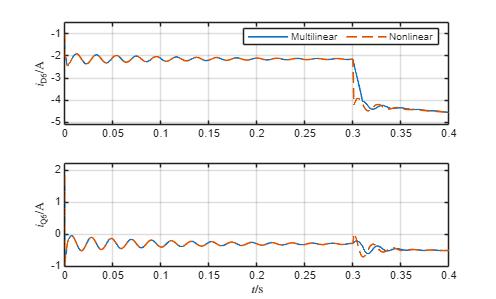


%% Current plots

figure(2)

% Indicies for the line currents
fd_indices = 15*num_inv+1:2:15*num_inv+2*Lines;
fq_indices = 15*num_inv+2:2:15*num_inv+2*Lines;

% Plot line 6 (between busses 6 and 7)

% d component
subplot(2,1,1)
plot(sys_simulation.tsim,sys_simulation.x(:,fd_indices(6)),LineWidth=1.2)
hold on
plot(tSol_nl,ySol_nl(:,fd_indices(6)),'LineStyle', '--',LineWidth=1.2)
legend("Multilinear","Nonlinear",'Orientation','horizontal')
ylabel('$i_{\rm{D}6}/\textrm{A}$','Interpreter','latex')
ylim([-5.1 -0.5])
grid
xlim([0 0.4])

% q component
subplot(2,1,2)
plot(sys_simulation.tsim,sys_simulation.x(:,fq_indices(6)),LineWidth=1.2)
hold on
plot(tSol_nl,ySol_nl(:,fq_indices(6)),'LineStyle', '--',LineWidth=1.2)
ylabel('$i_{\rm{Q}6}/\textrm{A}$','Interpreter','latex')
xlabel('$t/\textrm{s}$','Interpreter','latex')
ylim([-1 2.2])
grid 
xlim([0 0.4])

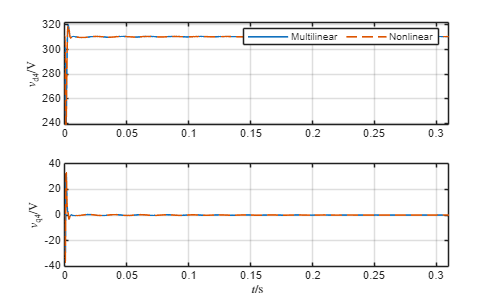


%% Local inverter voltage 
figure(3)

vd_indices = 11*num_inv+1:2:13*num_inv;
vq_indices = 11*num_inv+2:2:13*num_inv;

% Plot local voltage output of inverter 4
subplot(2,1,1)
plot(sys_simulation.tsim,sys_simulation.x(:,vd_indices(4)),LineWidth=1.2)
hold on
plot(tSol_nl,ySol_nl(:,vd_indices(4)),'LineStyle', '--',LineWidth=1.2)
legend("Multilinear","Nonlinear",'Orientation','horizontal')
ylabel('$v_{\rm{d}4}/\textrm{V}$','Interpreter','latex')
ylim([239 322])
grid
xlim([0 0.31])

subplot(2,1,2)
plot(sys_simulation.tsim,sys_simulation.x(:,vq_indices(4)),LineWidth=1.2)
hold on
plot(tSol_nl,ySol_nl(:,vq_indices(4)),'LineStyle', '--',LineWidth=1.2)
ylabel('$v_{\rm{q}4}/\textrm{V}$','Interpreter','latex')
xlabel('$t/\textrm{s}$','Interpreter','latex')
ylim([-40 40])
grid 
xlim([0 0.31])

### References

[1] - M. Kabalan, P. Singh and D. Niebur, "A Design and Optimization Tool for Inverter-Based Microgrids Using Large-Signal Nonlinear Analysis," in *IEEE Transactions on Smart Grid*, vol. 10, no. 4, pp. 4566-4576, July 2019

[2] - V. Mehrmann, B. Engquist, "Index Concepts for Differential-Algebraic Equations," in Encyclopedia of Applied and Computational Mathematics, Springer Berlin Heidelberg, pp. 676--681, 2015

[3] -  G. Lichtenberg, G. Pangalos, C. Cateriano Yáñez, A. Luxa,  N. Jöres, L. Schnelle, C. Kaufmann, "Implicit multilinear modeling: An introduction with application to energy systems," at - Automatisierungstechnik. 70. 13-30.,  2022